# TASK 1

% Параметры варианта
p = 1; % Вещественные полюса
q = 4; % Комплексно-сопряженные полюса
n = 4; % Количество неустойчивых полюсов разомкнутой системы
m = 4; % Количество неустойчивых полюсов замкнутой системы

% 1. Передаточные функции

syms s
%w1
Q1 = (s+1)*(s-1-1i)*(s-1+1i)*(s-2-1i)*(s-2+1i);
D1 = (s+2)*(s-1-2i)*(s-1+2i)*(s-2-2i)*(s-2+2i);
R1 = D1 - Q1;
simplify(R1)

$$ans = s^{4}+9\,s^{2}-24\,s+70$$

num1 = double(coeffs(R1, 'All'))

num1 =      1     0     9   -24    70


den1 = double(coeffs(Q1, 'All'))

den1 =      1    -5     9    -3    -8    10


W1 = tf(num1, den1);

%w2
Q2 = (s+1)*(s+1-1i)*(s+1+1i)*(s+2-1i)*(s+2+1i);
D2 = (s+2)*(s-1-2i)*(s-1+2i)*(s-2-2i)*(s-2+2i);
R2 = D2 - Q2;
simplify(R2)

$$ans = -11\,s^{4}-12\,s^{3}-27\,s^{2}-60\,s+70$$


num2 = double(coeffs(R2, 'All'))

num2 =    -11   -12   -27   -60    70


den2 = double(coeffs(Q2, 'All'))

den2 =      1     7    21    33    28    10


W2 = tf(num2, den2);

% w3
Q3 = (s+1)*(s-1-1i)*(s-1+1i)*(s-2-1i)*(s-2+1i);
D3 = (s+2)*(s+1-1i)*(s+1+1i)*(s+2-1i)*(s+2+1i);
R3 = D3 - Q3;
simplify(R3)

$$ans = 13\,s^{4}+18\,s^{3}+51\,s^{2}+54\,s+10$$


num3 = double(coeffs(R3, 'All'))

num3 =     13    18    51    54    10


den3 = double(coeffs(Q3, 'All'))

den3 =      1    -5     9    -3    -8    10


W3 = tf(num3, den3);

% Замкнутые системы
CL1 = feedback(W1, 1);
CL2 = feedback(W2, 1);
CL3 = feedback(W3, 1);


## system 1

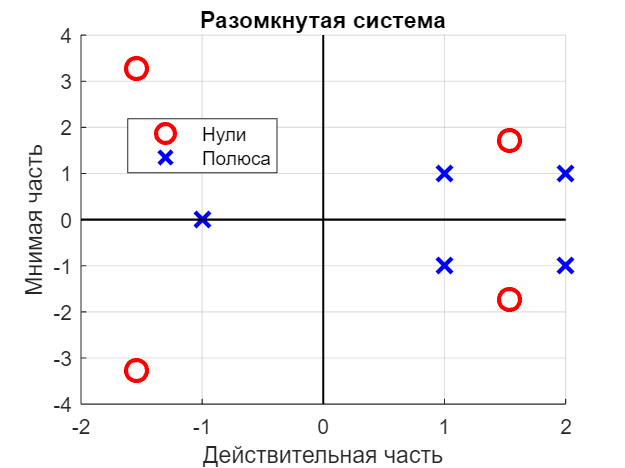

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_1_map_ol.png


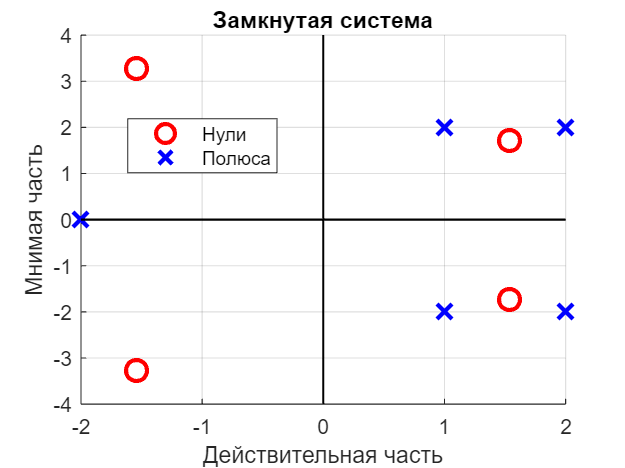

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_1_map_cl.png


map(W1, CL1, 'W1', '1_1_map');

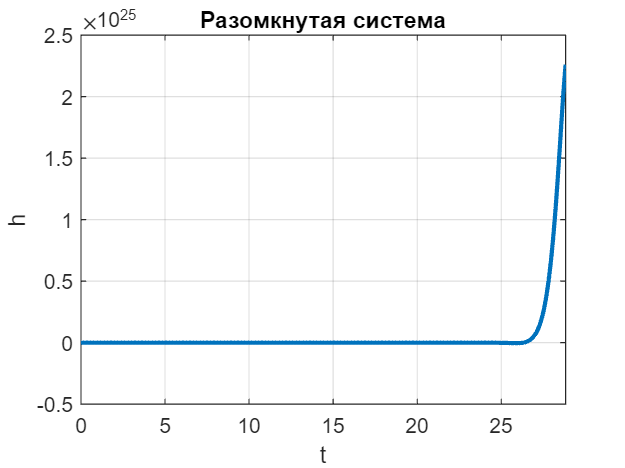

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_1_h_ol.png


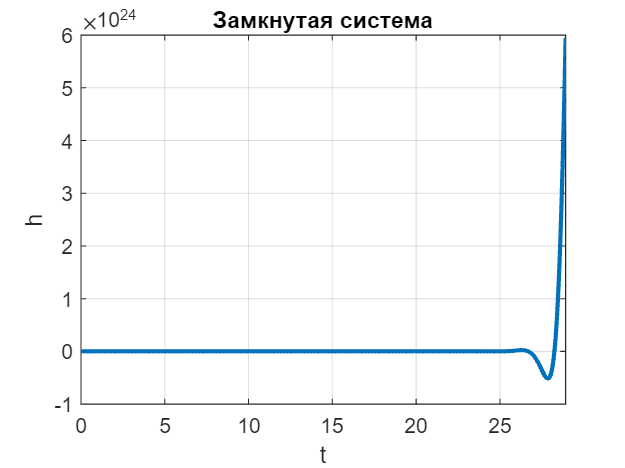

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_1_h_cl.png


transition(W1, CL1, '1_1_h');

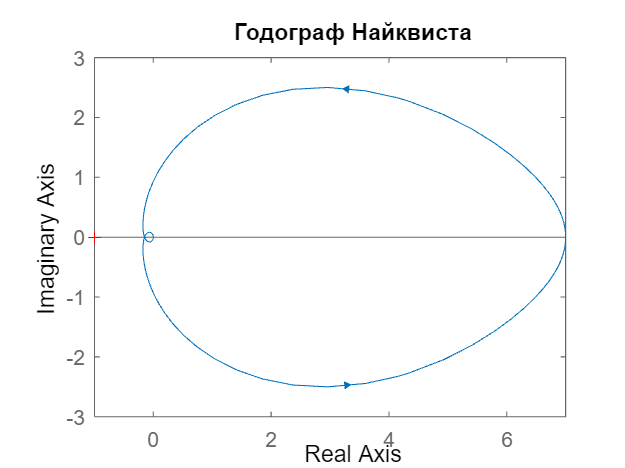

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_1_hod.png


hodograph(W1,'W1','1_1');

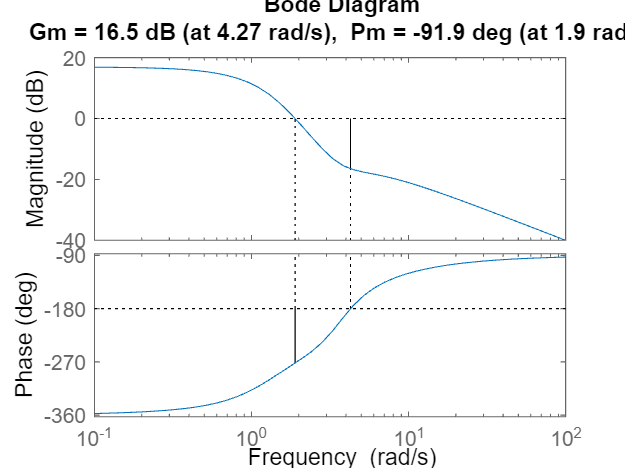

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_1_lapfs.png


lapfs(W1,'W1','1_1');

## system 2

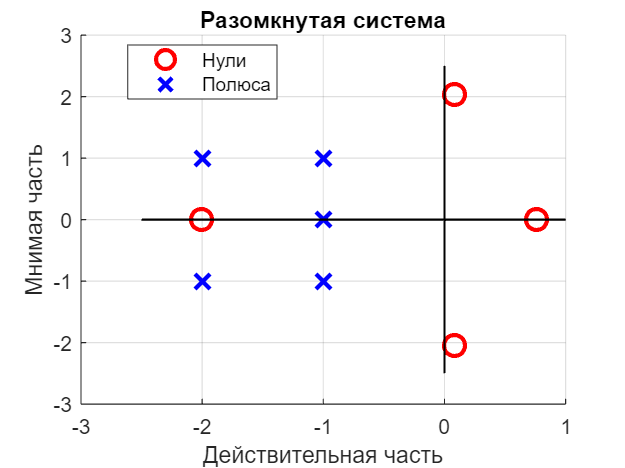

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_2_map_ol.png


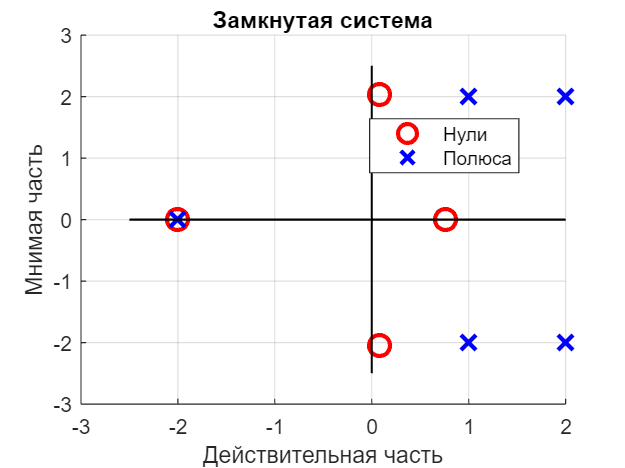

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_2_map_cl.png


map(W2, CL2, 'W2', '1_2_map');

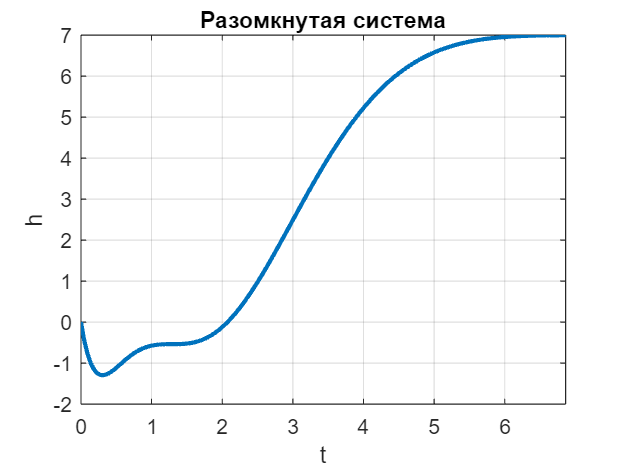

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_2_h_ol.png


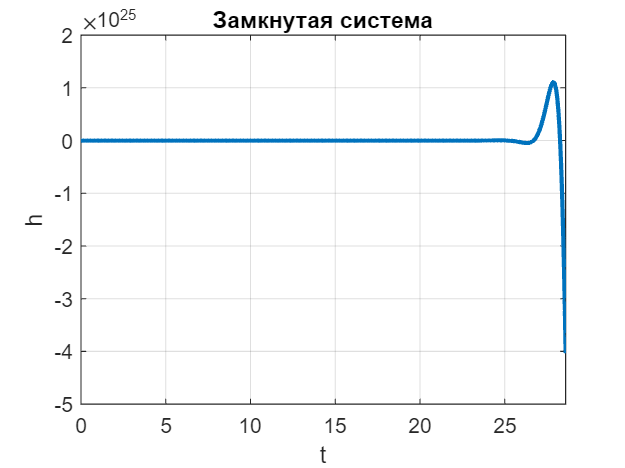

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_2_h_cl.png


transition(W2, CL2, '1_2_h');

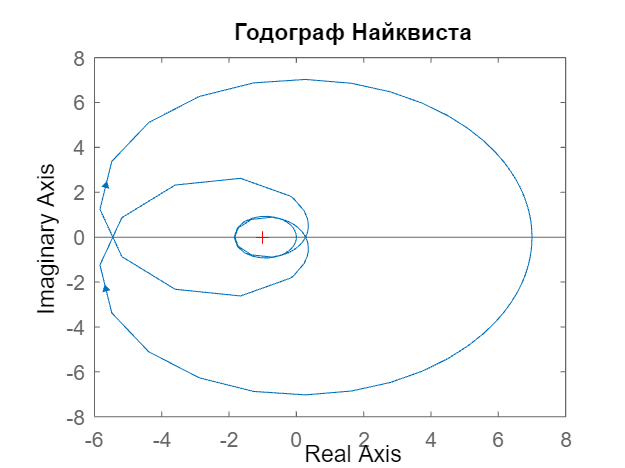

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_2_hod.png


hodograph(W2,'W2','1_2');

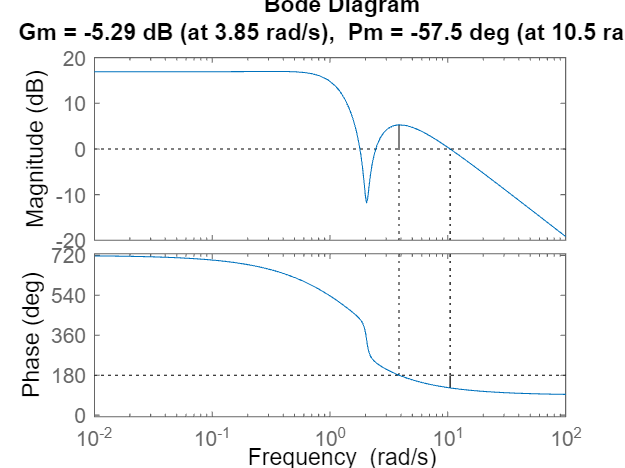

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_2_lapfs.png


lapfs(W2,'W2','1_2');

## system 3

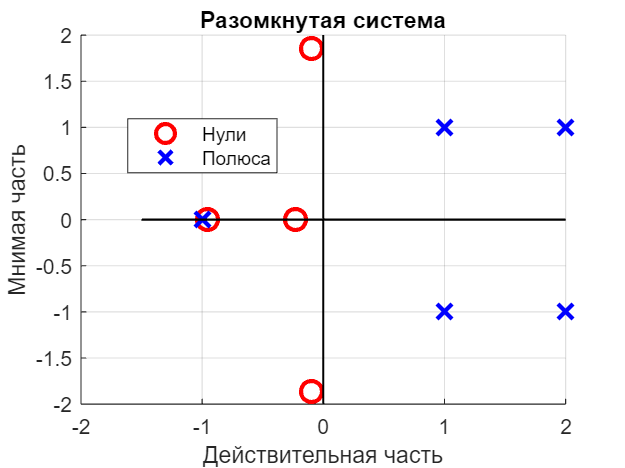

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_3_map_ol.png


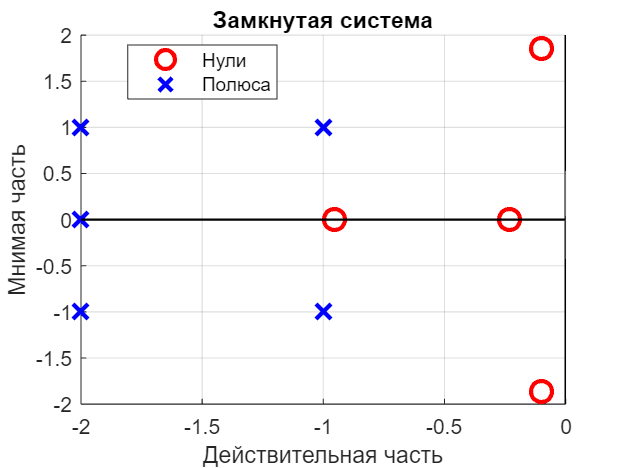

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_3_map_cl.png


map(W3, CL3, 'W3', '1_3_map');

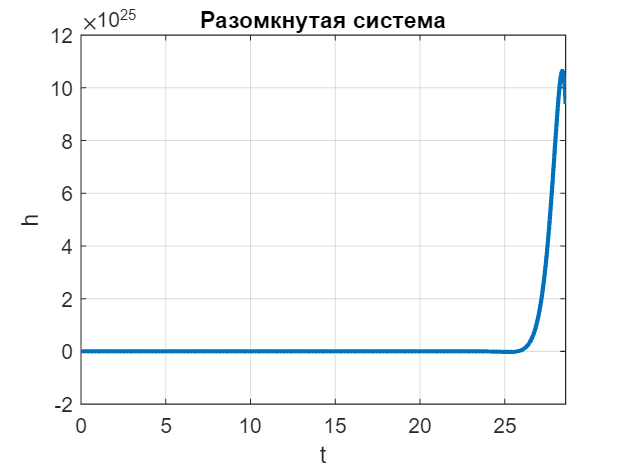

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_3_h_ol.png


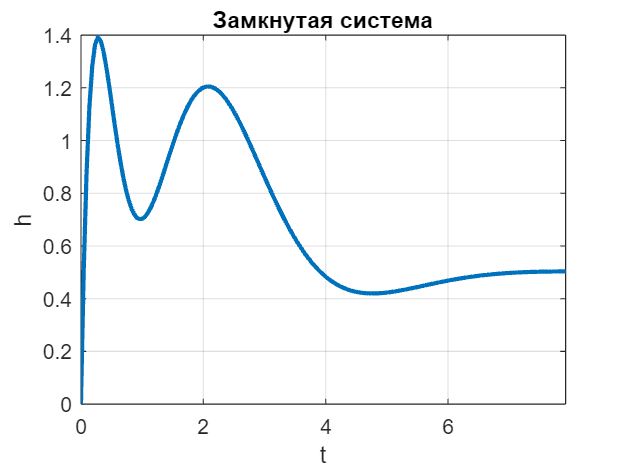

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_3_h_cl.png


transition(W3, CL3, '1_3_h');

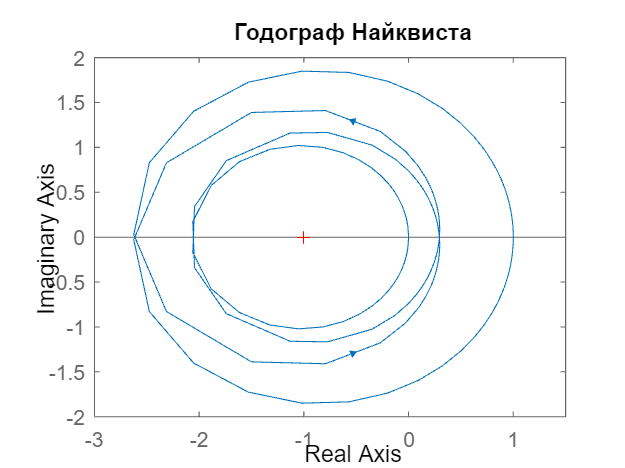

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_3_hod.png


hodograph(W3,'W3','1_3');

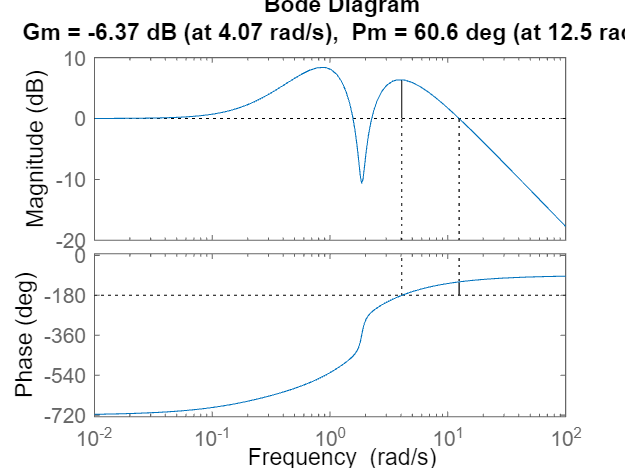

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\1_3_lapfs.png


lapfs(W3,'W3','1_3');

# TASK 2

## W1 k values

% num1 = [1 -3];
% den1 = [1 7 4];
num1 = [1 -1];
den1 = [1 6 7];
k1 = 2

k1 = 2

k2 = 5

k2 = 5

k3 = 10

k3 = 10

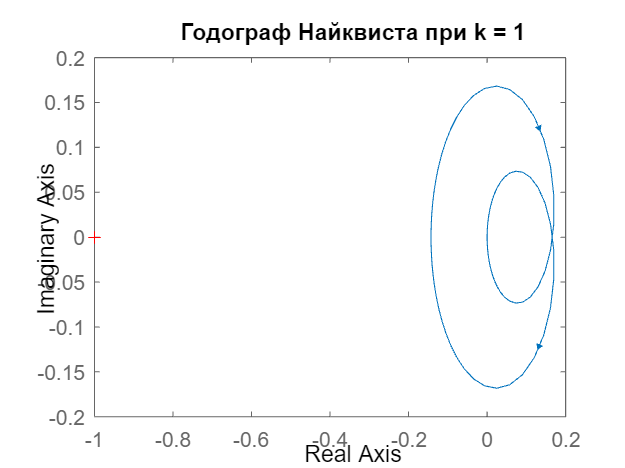

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\2_1_0_hod.png



W1 = tf(num1, den1);
hodograph_2(W1, 'W1', '2_1_0', 1, 0);

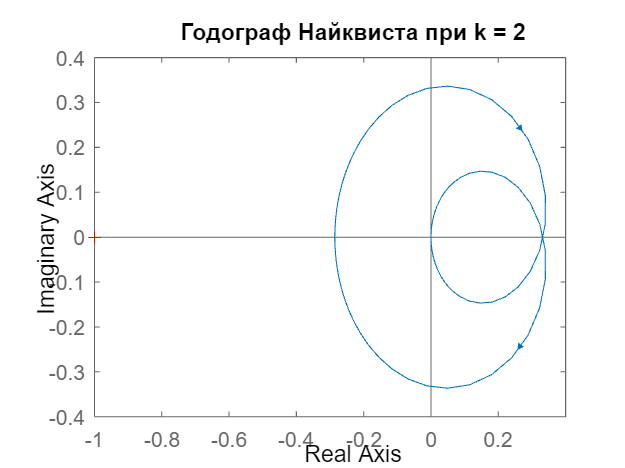

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\2_1_1_hod.png



W1 = k1 * tf(num1, den1);
hodograph_2(W1, 'W1', '2_1_1', k1, 0);

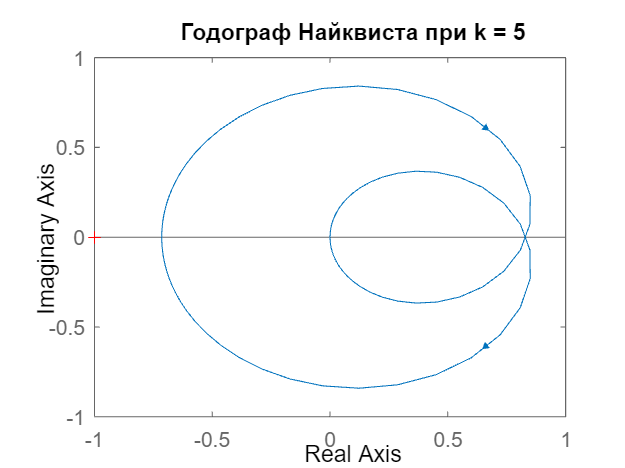

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\2_1_2_hod.png



W1 = k2 * tf(num1, den1);
hodograph_2(W1, 'W1', '2_1_2', k2, 0);

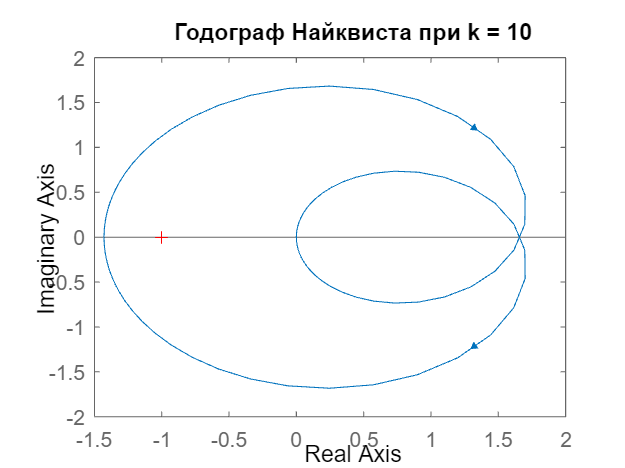

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\2_1_3_hod.png



W1 = k3 * tf(num1, den1);
hodograph_2(W1, 'W1', '2_1_3', k3, 0);

## W1 teor

syms w real

num = 1i*w - 1;
den = (1i*w)^2 + 6i*w + 7;
% num = 1i*w - 3;
% den = (1i*w)^2 + 7i*w + 4;
W = simplify(expand(num * conj(den))/expand(den*conj(den)))

$$W = \frac{-w^{3}\,\mathrm{i}+7\,w^{2}+13\,w\,\mathrm{i}-7}{w^{4}+22\,w^{2}+49}$$

u = real(W)

$$u = \frac{7\,w^{2}-7}{w^{4}+22\,w^{2}+49}$$

v = imag(W)

$$v = \frac{13\,w-w^{3}}{w^{4}+22\,w^{2}+49}$$

A = simplify(sqrt(expand(u^2 + v^2)))

$$A = \frac{\sqrt{w^{2}+1}}{\sqrt{w^{4}+22\,w^{2}+49}}$$

phase_f = atan2(v, u)

$$phase\_f = \text{atan2}\left(13\,w-w^{3},7\,w^{2}-7\right)$$

solve(simplify(v*expand(den*conj(den))))

$$ans = \left(\begin{array}{c} 0\\ \sqrt{13}\\ -\sqrt{13} \end{array}\right)$$

w_crit = 0;
subs(phase_f, w, 0)

$$ans = \pi$$

double(ans)

ans = 3.1416

k_max = simplify(subs(A^(-1), w, w_crit))

$$k\_max = 7$$

## W1 step response

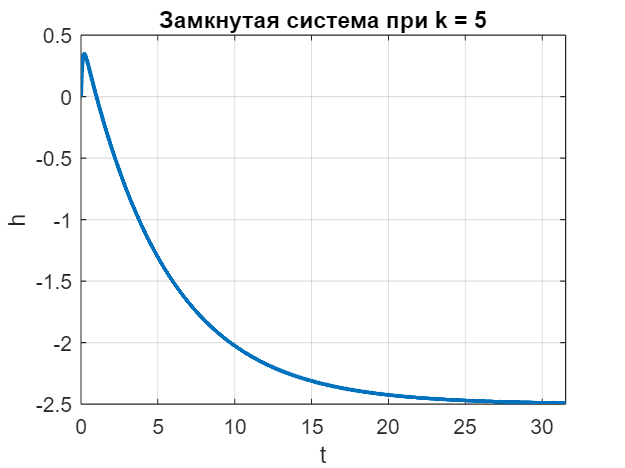

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\2_1_1_cl.png


W1 = k2 * tf(num1, den1);
CL1 = feedback(W1, 1);
transition_cl2(CL1, '2_1_1', k2);

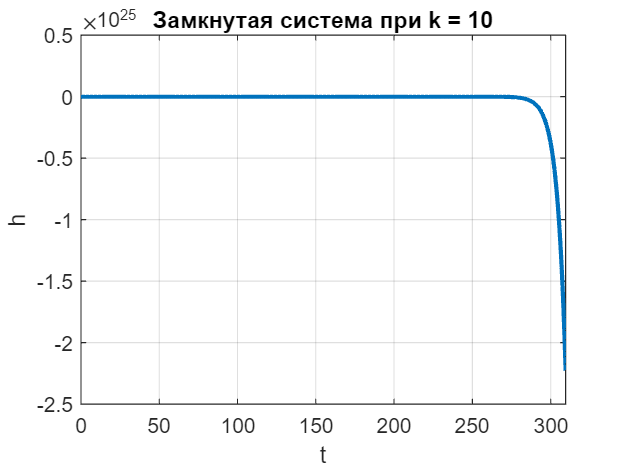

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\2_1_2_cl.png



W1 = k3 * tf(num1, den1);
CL1 = feedback(W1, 1);
transition_cl2(CL1, '2_1_2', k3);

## W2 k values

num1 = [10 15 18 6];
den1 = [10 -10 0 0];

k1 = 0.3

k1 = 0.3000

k2 = 2

k2 = 2

k3 = 5

k3 = 5

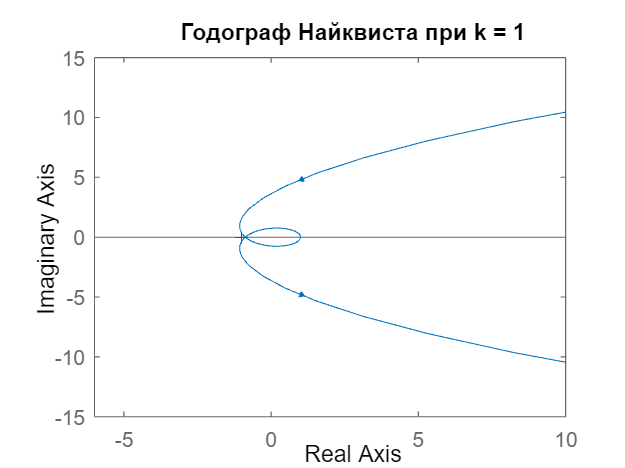

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\2_2_0_hod.png



W1 = tf(num1, den1);
hodograph_2(W1, 'W1', '2_2_0', 1, 1);

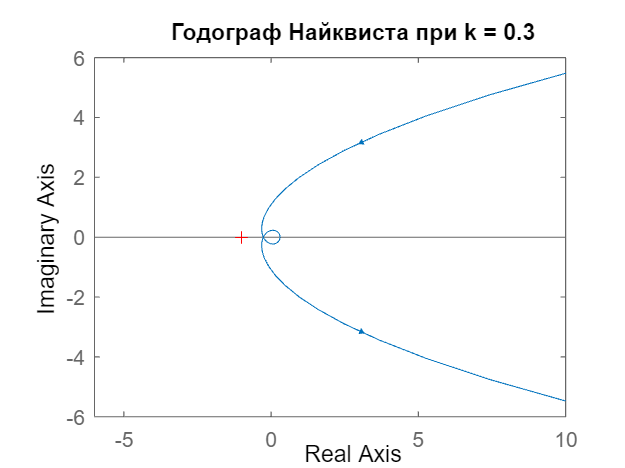

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\2_2_1_hod.png



W1 = k1 * tf(num1, den1);
hodograph_2(W1, 'W1', '2_2_1', k1, 1);

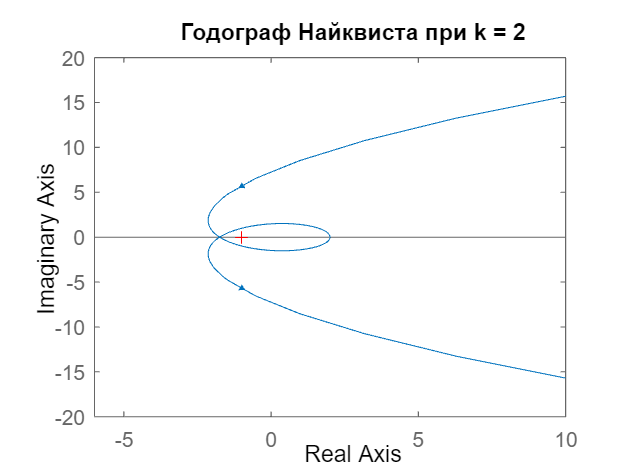

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\2_2_2_hod.png



W1 = k2 * tf(num1, den1);
hodograph_2(W1, 'W1', '2_2_2', k2, 1);

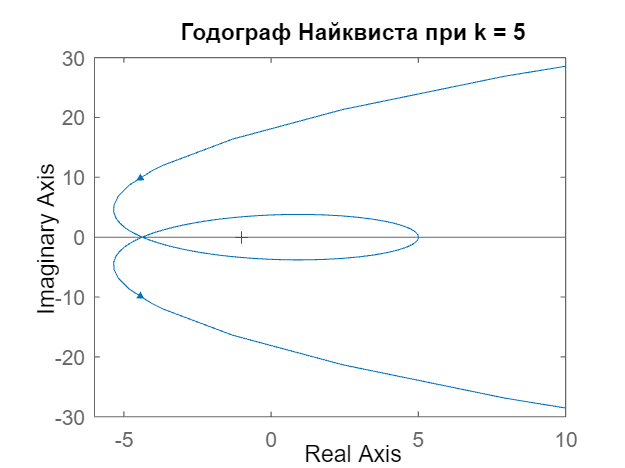

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\2_2_3_hod.png



W1 = k3 * tf(num1, den1);
hodograph_2(W1, 'W1', '2_2_3', k3, 1);

## W2 teor

syms omega real

num = 10*(1i*omega)^3 + 15*(1i*omega)^2 + 18*(1i*omega) + 6;
den = 10*(1i*omega)^3 - 10*(1i*omega)^2;
% num = 100*(1i*w)^2 + 40*(1i*w) + 4;
% den = 100*(1i*w)^3 - 15*(1i*w)^2 - 8*(1i*w) - 0.6;
W = (expand(num * conj(den))/expand(den*conj(den)))

$$W = \frac{100\,\omega^{6}-250\,\omega^{5}\,\mathrm{i}-330\,\omega^{4}+240\,\omega^{3}\,\mathrm{i}+60\,\omega^{2}}{100\,\omega^{6}+100\,\omega^{4}}$$

disp(latex(num))

-\omega ^3\,10{}\mathrm{i}-15\,\omega ^2+\omega \,18{}\mathrm{i}+6


disp(latex(den))

10\,\omega ^2-\omega ^3\,10{}\mathrm{i}


disp(latex(W))

\frac{100\,\omega ^6-\omega ^5\,250{}\mathrm{i}-330\,\omega ^4+\omega ^3\,240{}\mathrm{i}+60\,\omega ^2}{100\,\omega ^6+100\,\omega ^4}


u = real(W)

$$u = \frac{100\,\omega^{6}-330\,\omega^{4}+60\,\omega^{2}}{100\,\omega^{6}+100\,\omega^{4}}$$

v = imag(W)

$$v = \frac{240\,\omega^{3}-250\,\omega^{5}}{100\,\omega^{6}+100\,\omega^{4}}$$

A = simplify(sqrt(expand(u^2 + v^2)))

$$A = \frac{\sqrt{100\,\omega^{6}-135\,\omega^{4}+144\,\omega^{2}+36}}{10\,\omega^{2}\,\sqrt{\omega^{2}+1}}$$

phase_f = atan2(v, u)

$$phase\_f = \text{atan2}\left(\frac{240\,\omega^{3}-250\,\omega^{5}}{100\,\omega^{6}+100\,\omega^{4}},\frac{100\,\omega^{6}-330\,\omega^{4}+60\,\omega^{2}}{100\,\omega^{6}+100\,\omega^{4}}\right)$$

disp(latex(A))

\frac{\sqrt{100\,\omega ^6-135\,\omega ^4+144\,\omega ^2+36}}{10\,\omega ^2\,\sqrt{\omega ^2+1}}


disp(latex(phase_f))

\mathrm{atan2}\left(\frac{240\,\omega ^3-250\,\omega ^5}{100\,\omega ^6+100\,\omega ^4},\frac{100\,\omega ^6-330\,\omega ^4+60\,\omega ^2}{100\,\omega ^6+100\,\omega ^4}\right)


sol = solve(simplify(v*expand(den*conj(den))))

$$sol = \left(\begin{array}{c} 0\\ 0\\ 0\\ -\frac{2\,\sqrt{6}}{5}\\ \frac{2\,\sqrt{6}}{5} \end{array}\right)$$

w_crit = max(sol);
subs(phase_f, omega, w_crit)

$$ans = \pi$$

double(ans)

ans = 3.1416

k_min = simplify(subs(A^(-1), omega, w_crit))

$$k\_min = \frac{8}{7}$$

## W2 step response

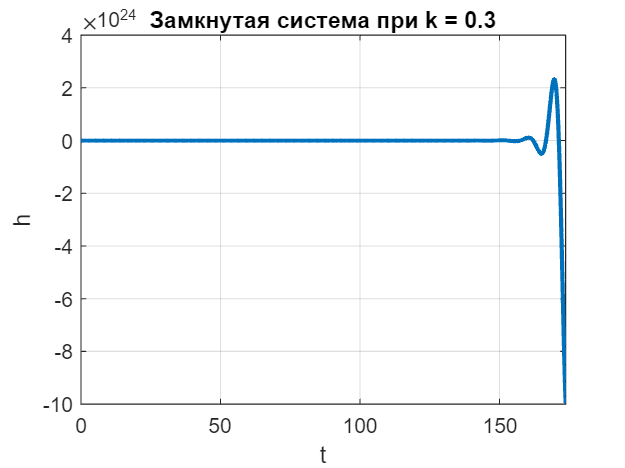

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\2_2_1_cl.png


W1 = k1 * tf(num1, den1);
CL1 = feedback(W1, 1);
transition_cl2(CL1, '2_2_1', k1);

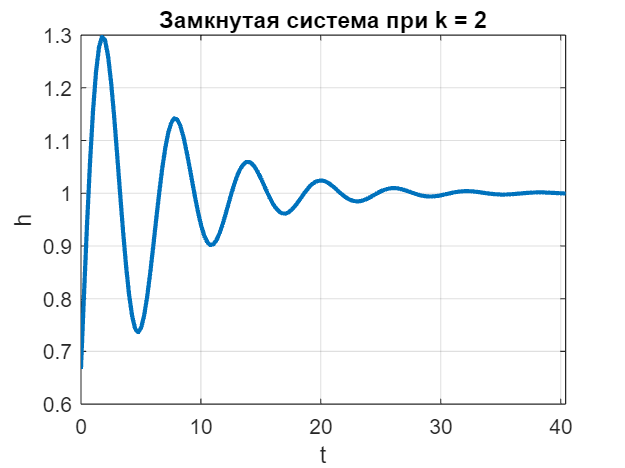

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\2_2_2_cl.png



W1 = k2 * tf(num1, den1);
CL1 = feedback(W1, 1);
transition_cl2(CL1, '2_2_2', k2);

# TASK 3

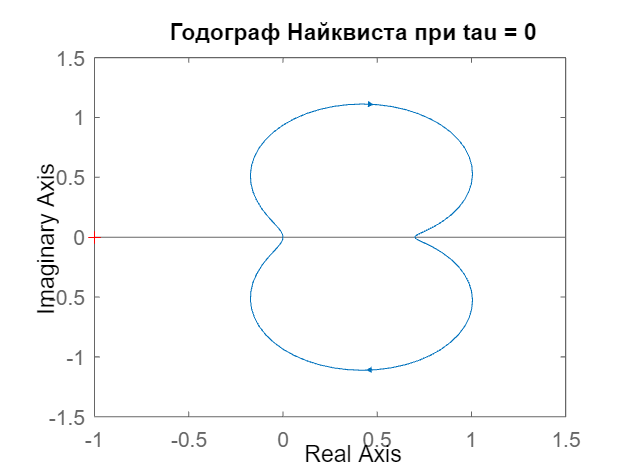

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_1_0_hod.png


tau1 = 0;
num4 = [1 7];
den4 = [1 2 10];
W4 = tf(num4, den4, 'InputDelay', tau1);
hodograph_3(W4, 'W3', '3_1_0', tau1);

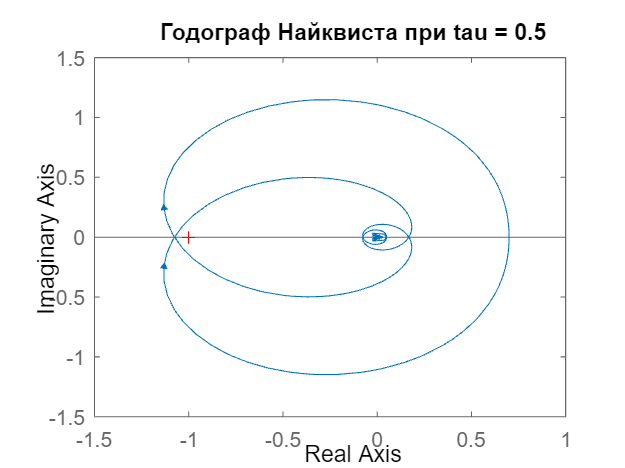

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_1_1_hod.png



tau1 = 0.5;
W4 = tf(num4, den4, 'InputDelay', tau1);
hodograph_3(W4, 'W3', '3_1_1', tau1);

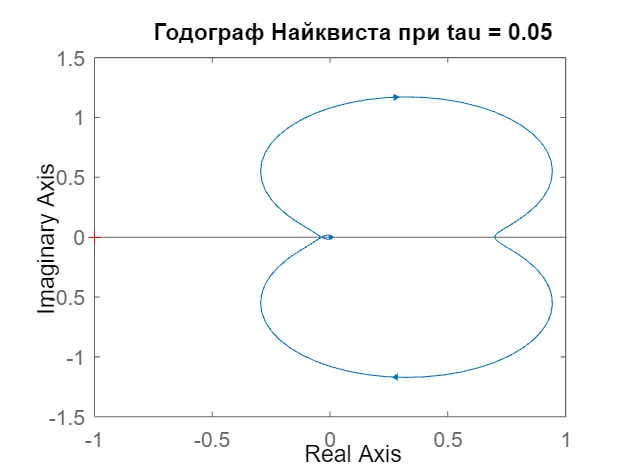

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_1_2_hod.png



tau1 = 0.05;
W4 = tf(num4, den4, 'InputDelay', tau1);
hodograph_3(W4, 'W3', '3_1_2', tau1);

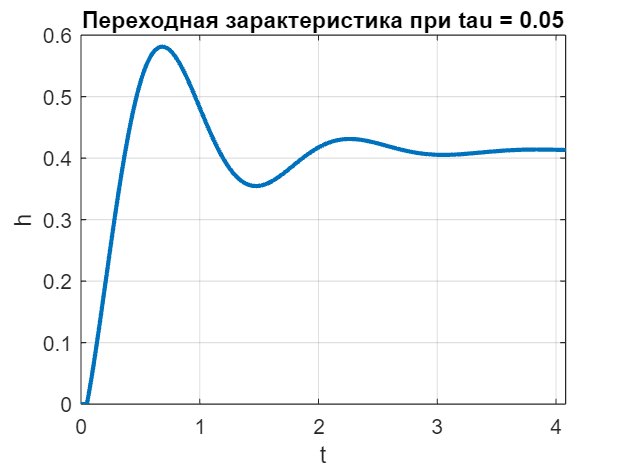

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_1_5_cl.png


CL4 = feedback(W4, 1);
transition_cl3(CL4, '3_1_5', tau1);

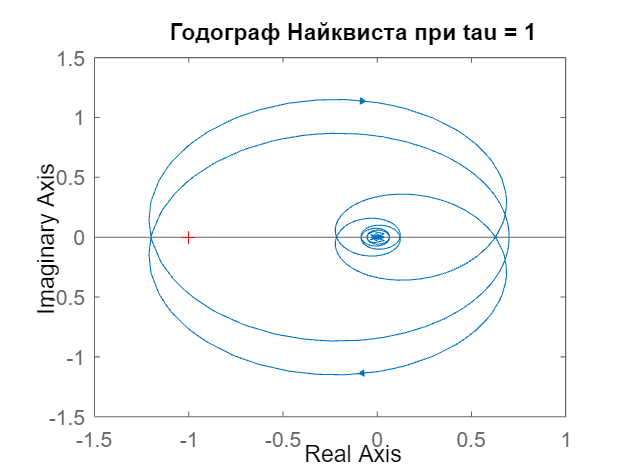

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_1_3_hod.png



tau1 = 1;
W4 = tf(num4, den4, 'InputDelay', tau1);
hodograph_3(W4, 'W3', '3_1_3', tau1);

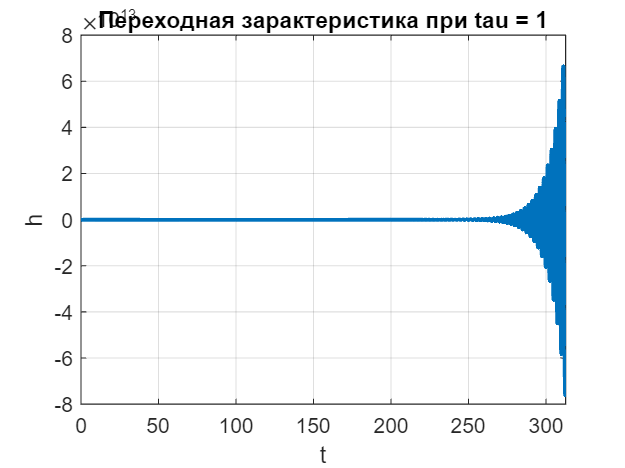

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_1_6_cl.png


CL4 = feedback(W4, 1);
transition_cl3(CL4, '3_1_6', tau1);

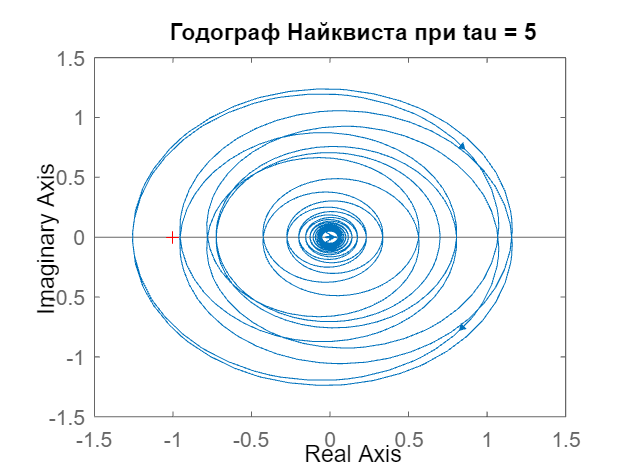

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_1_4_hod.png



tau1 = 5;
W4 = tf(num4, den4, 'InputDelay', tau1);
hodograph_3(W4, 'W3', '3_1_4', tau1);

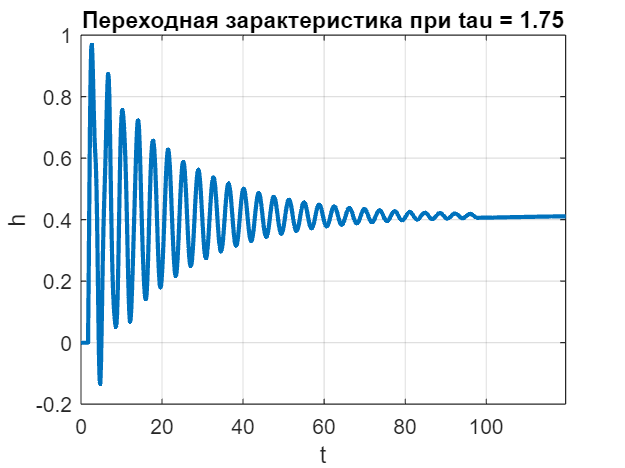

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_1_7_cl.png



tau1 = 1.75;
W4 = tf(num4, den4, 'InputDelay', tau1);
CL4 = feedback(W4, 1);
transition_cl3(CL4, '3_1_7', tau1);

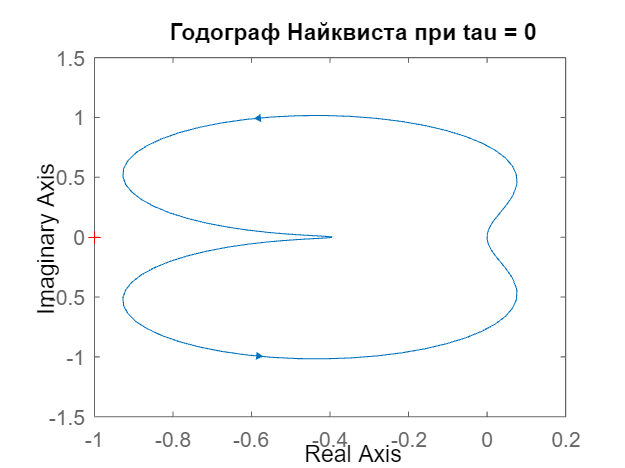

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_2_0_hod.png


tau2 = 0;
num5 = [10 -5 -15];
den5 = [10 5 10 38];
W5 = tf(num5, den5, 'InputDelay', tau2);
hodograph_3(W5, 'W4', '3_2_0', tau2);

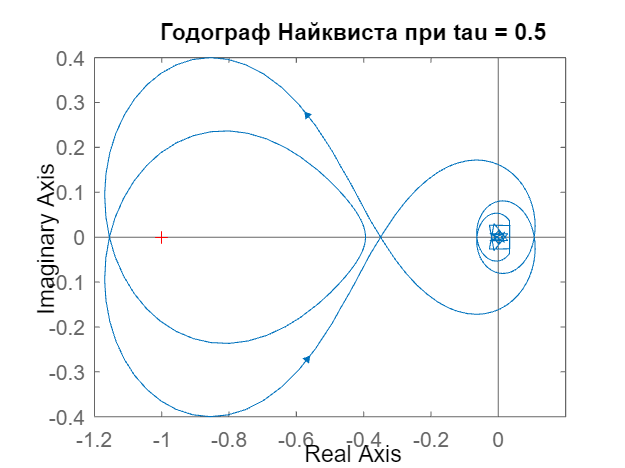

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_2_1_hod.png



tau2 = 0.5;
W5 = tf(num5, den5, 'InputDelay', tau2);
hodograph_3(W5, 'W4', '3_2_1', tau2);

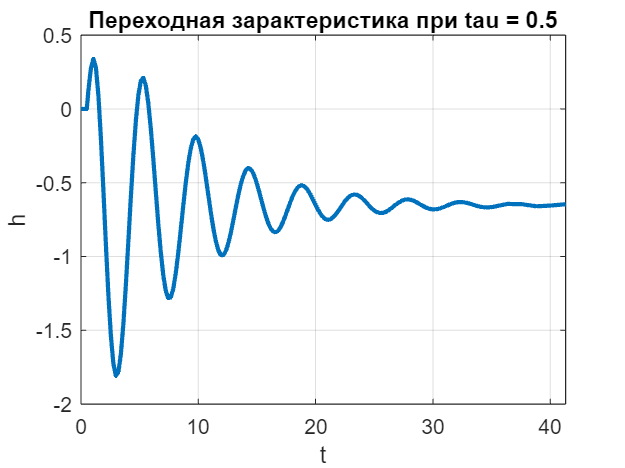

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_2_6_cl.png


CL5 = feedback(W5, 1);
transition_cl3(CL5, '3_2_6', tau2);

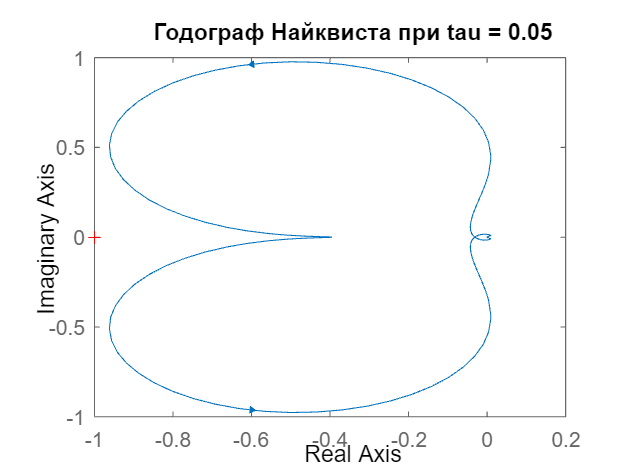

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_2_2_hod.png



tau2 = 0.05;
W5 = tf(num5, den5, 'InputDelay', tau2);
hodograph_3(W5, 'W4', '3_2_2', tau2);

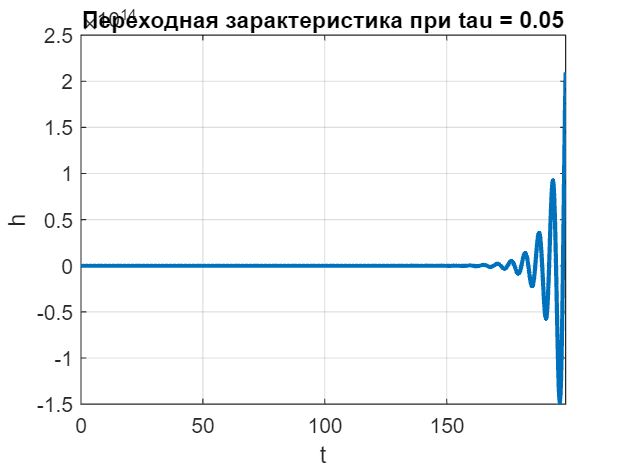

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_2_5_cl.png


CL5 = feedback(W5, 1);
transition_cl3(CL5, '3_2_5', tau2);

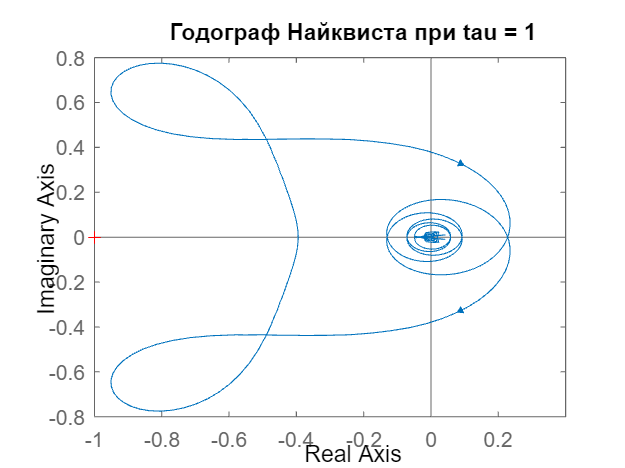

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_2_3_hod.png



tau2 = 1;
W5 = tf(num5, den5, 'InputDelay', tau2);
hodograph_3(W5, 'W4', '3_2_3', tau2);

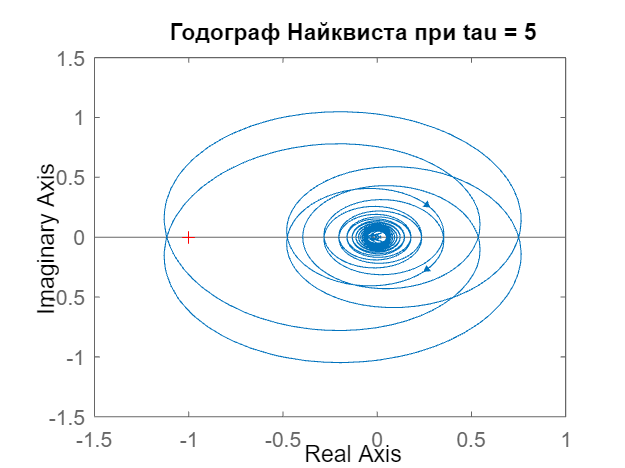

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_2_4_hod.png



tau2 = 5;
W5 = tf(num5, den5, 'InputDelay', tau2);
hodograph_3(W5, 'W4', '3_2_4', tau2);

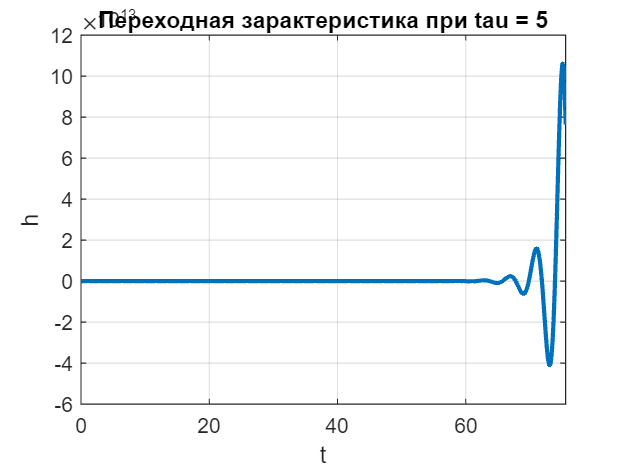

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab6\report\images\3_2_7_cl.png


CL5 = feedback(W5, 1);
transition_cl3(CL5, '3_2_7', tau2);

x = sym('w')

$$x = w$$

u = (-5*x^2+70)/(x^4-16*x^2+100)

$$u = -\frac{5\,w^{2}-70}{w^{4}-16\,w^{2}+100}$$

v = (-x^3-4*x)/(x^4-16*x^2+100)

$$v = -\frac{w^{3}+4\,w}{w^{4}-16\,w^{2}+100}$$

A = simplify(sqrt(expand(u^2+v^2)))

$$A = \frac{\sqrt{w^{2}+49}}{\sqrt{w^{4}-16\,w^{2}+100}}$$

simplify(solve(A == 1))

$$ans = \left(\begin{array}{c} -\frac{\sqrt{2}\,\sqrt{17-\sqrt{85}}}{2}\\ \frac{\sqrt{2}\,\sqrt{17-\sqrt{85}}}{2}\\ -\frac{\sqrt{2}\,\sqrt{\sqrt{85}+17}}{2}\\ \frac{\sqrt{2}\,\sqrt{\sqrt{85}+17}}{2} \end{array}\right)$$

phi = atan2((-x^3-4*x)/(x^4-16*x^2+100), (-5*x^2+70)/(x^4-16*x^2+100))

$$phi = \text{atan2}\left(-\frac{w^{3}+4\,w}{w^{4}-16\,w^{2}+100},-\frac{5\,w^{2}-70}{w^{4}-16\,w^{2}+100}\right)$$

a = (sqrt((2))*sqrt(17 - sqrt(85)))/2

a = 1.9724

b = (sqrt((2))*sqrt(17 + sqrt(85)))/2

b = 3.6207

c = -(sqrt((2))*sqrt(17 - sqrt(85)))/2

c = -1.9724

d = -(sqrt((2))*sqrt(17 + sqrt(85)))/2

d = -3.6207

phi1 = atan2((-a^3-4*a)/(a^4-16*a^2+100), (-5*a^2+70)/(a^4-16*a^2+100))

phi1 = -0.2987

phi2 = atan2((-b^3-4*b)/(b^4-16*b^2+100), (-5*b^2+70)/(b^4-16*b^2+100))

phi2 = -1.4991

phi3 = atan2((-c^3-4*c)/(c^4-16*c^2+100), (-5*c^2+70)/(c^4-16*c^2+100))

phi3 = 0.2987

phi4 = atan2((-d^3-4*d)/(d^4-16*d^2+100), (-5*d^2+70)/(d^4-16*d^2+100))

phi4 = 1.4991

% s = tf('s');
% W3 = (s + 7) / (s^2 + 2*s + 10);
% W4 = (10*s^2 - 5*s - 15) / (10*s^3 + 5*s^2 + 10*s + 38);
% 
% tau_values = linspace(0, 3, 10000);
% order_pade = 5;
% 
% tau_stability_W3 = [];
% tau_stability_W4 = [];
% 
% for tau = tau_values
% 
%     delay_pade = pade(exp(-tau * s), order_pade);
% 
%     W3_delayed = W3 * delay_pade;
%     W4_delayed = W4 * delay_pade;
% 
%     CL3 = feedback(W3_delayed, 1);
%     CL4 = feedback(W4_delayed, 1);
% 
%     is_stable_W3 = isstable(CL3);
%     is_stable_W4 = isstable(CL4);
% 
%     if is_stable_W3
%         tau_stability_W3 = [tau_stability_W3, tau];
%     end
%     if is_stable_W4
%         tau_stability_W4 = [tau_stability_W4, tau];
%     end
% end
% 
% if ~isempty(tau_stability_W3)
%     fprintf('Пределы устойчивости W3: τ ∈ [%.3f, %.3f]\n', min(tau_stability_W3), max(tau_stability_W3));
% else
%     disp('Система W3 неустойчива для всех значений τ.');
% end

Пределы устойчивости W3: τ ∈ [0.000, 2.236]


% 
% if ~isempty(tau_stability_W4)
%     fprintf('Пределы устойчивости W4: τ ∈ [%.3f, %.3f]\n', min(tau_stability_W4), max(tau_stability_W4));
% else
%     disp('Система W4 неустойчива для всех значений τ.');
% end

Пределы устойчивости W4: τ ∈ [0.338, 0.717]


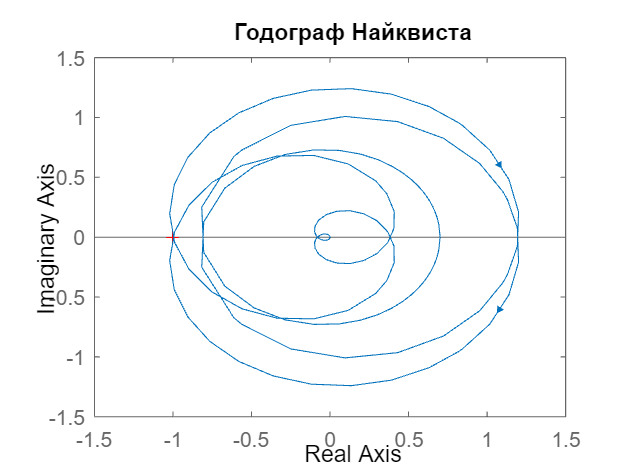

% 
% if ~isempty(tau_stability_W3)
%     figure;
%     delay_pade = pade(exp(-max(tau_stability_W3) * s), order_pade);
%     W3_delayed = W3 * delay_pade;
%     nyquist(W3_delayed);
%     title('Годограф Найквиста');
%     save_plot(fig, '3_1_hd.png')
%     % grid on;
% end

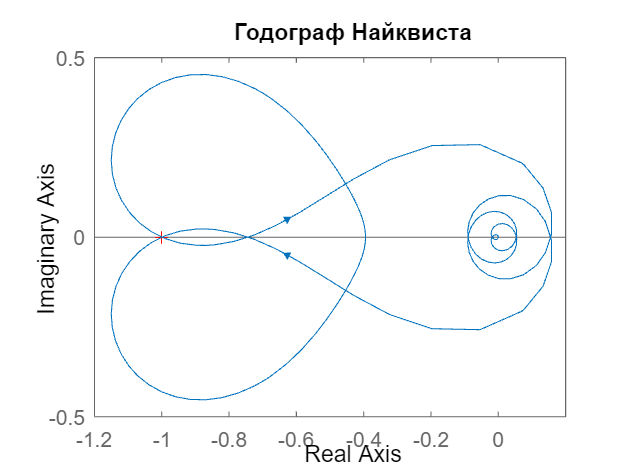

% 
% if ~isempty(tau_stability_W4)
%     figure;
%     delay_pade = pade(exp(-max(tau_stability_W4) * s), order_pade);
%     W4_delayed = W4 * delay_pade;
%     nyquist(W4_delayed);
%     title('Годограф Найквиста');
%     save_plot(fig, '3_2_hd.png')
%     % grid on;
% end

# FUNCTIONS

function map(open_loop_system, closed_loop_system, name, filename)
    % Полюса и нули разомкнутой системы
    poles_open = pole(open_loop_system);
    zeros_open = zero(open_loop_system);
    
    % Полюса и нули замкнутой системы
    poles_closed = pole(closed_loop_system);
    zeros_closed = zero(closed_loop_system);
    
    % Построение карты полюсов и нулей разомкнутой системы
    fig = figure;
    hold on;
    plot(real(zeros_open), imag(zeros_open), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Нули'); % Нули (красные кружки)
    plot(real(poles_open), imag(poles_open), 'bx', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Полюса'); % Полюса (синие кресты)
    h_x = line(xlim, [0 0], 'Color', 'k', 'LineWidth', 1); % Ось X
    h_y = line([0 0], ylim, 'Color', 'k', 'LineWidth', 1); % Ось Y
    set([h_x, h_y], 'HandleVisibility', 'off'); % Отключаем видимость в легенде
    xlabel('Действительная часть');
    ylabel('Мнимая часть');
    title('Разомкнутая система');
    legend('Location', 'best');
    grid on;
    hold off;
    save_plot(fig, [filename '_ol.png'])
    
    % Построение карты полюсов и нулей замкнутой системы
    fig = figure;
    hold on;
    plot(real(zeros_closed), imag(zeros_closed), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Нули'); % Нули (красные кружки)
    plot(real(poles_closed), imag(poles_closed), 'bx', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Полюса'); % Полюса (синие кресты)
    h_x = line(xlim, [0 0], 'Color', 'k', 'LineWidth', 1); % Ось X
    h_y = line([0 0], ylim, 'Color', 'k', 'LineWidth', 1); % Ось Y
    set([h_x, h_y], 'HandleVisibility', 'off'); % Отключаем видимость в легенде
    xlabel('Действительная часть');
    ylabel('Мнимая часть');
    title('Замкнутая система');
    legend('Location', 'best');
    grid on;
    hold off;
    save_plot(fig, [filename '_cl.png'])
end

function transition(open_loop_system, closed_loop_system, filename)
    transition_ol(open_loop_system, filename)
    transition_cl(closed_loop_system, filename)
end

function transition_cl(closed_loop_system, filename)
    fig = figure;
    [step_y, step_t] = step(closed_loop_system);
    plot(step_t, step_y, 'LineWidth', 2);
    h='Замкнутая система';
    title(h);
    xlabel('t');
    ylabel('h');
    grid on;
    xlim([0 max(step_t)])
    save_plot(fig, [filename '_cl.png'])
end

function transition_cl2(closed_loop_system, filename, k)
    fig = figure;
    [step_y, step_t] = step(closed_loop_system);
    plot(step_t, step_y, 'LineWidth', 2);
    h=['Переходная зарактеристика при k = ' num2str(k)];
    title(h);
    xlabel('t');
    ylabel('h');
    grid on;
    xlim([0 max(step_t)])
    save_plot(fig, [filename '_cl.png'])
end

function transition_cl3(closed_loop_system, filename, k)
    fig = figure;
    [step_y, step_t] = step(closed_loop_system);
    plot(step_t, step_y, 'LineWidth', 2);
    h=['Переходная зарактеристика при tau = ' num2str(k)];
    title(h);
    xlabel('t');
    ylabel('h');
    grid on;
    xlim([0 max(step_t)])
    save_plot(fig, [filename '_cl.png'])
end

function transition_ol(open_loop_system, filename)
    fig = figure;
    [step_y, step_t] = step(open_loop_system);
    plot(step_t, step_y, 'LineWidth', 2);
    h='Разомкнутая система';
    title(h);
    xlabel('t');
    ylabel('h');
    grid on;
    xlim([0 max(step_t)])
    save_plot(fig, [filename '_ol.png'])
end

function hodograph(W,a,filename)
    fig = figure;
    nyquist(W);
    h='Годограф Найквиста';
    title(h);
    save_plot(fig, [filename '_hod.png'])
end

function hodograph_2(W,a,filename, k, flag)
    fig = figure;
    nyquist(W);
    if flag == 1
        xlim([-6 10])
    end
    h=['Годограф Найквиста при k = ' num2str(k)];
    title(h);
    save_plot(fig, [filename '_hod.png'])
end

function hodograph_3(W,a,filename, k)
    fig = figure;
    nyquist(W);
    h=['Годограф Найквиста при tau = ' num2str(k)];
    title(h);
    save_plot(fig, [filename '_hod.png'])
end

function save_plot(fig, save_filename)
    save_path = 'C:\Users\vasil\Desktop\lsau\lab6\report\images'; % Замените на свой путь
    
    % Полный путь к файлу
    full_save_path = fullfile(save_path, save_filename);
    
    % Сохранение графика
    exportgraphics(fig, full_save_path, "Resolution", 600); 
    disp(['График сохранен по пути: ' full_save_path]);
end

function lapfs(W,a,filename)
    fig = figure;
    margin(W);
    save_plot(fig, [filename '_lapfs.png'])
end

% function lapfs(W,a,filename)
%     [mag, phase, omega] = bode(W);
%     mag = squeeze(mag);
%     phase = squeeze(phase);
%     fig = figure;
% 
%     subplot(2,1,1);
%     semilogx(omega, 20*log10(mag), 'LineWidth', 2);
%     h='Логарифмическая амплитудно-частотная характеристика (ЛАЧХ) для '+string(a);
%     title(h);
%     xlabel('Частота (рад/с)');
%     ylabel('Амплитуда (дБ)');
%     grid on;
% 
%     subplot(2,1,2);
%     semilogx(omega, phase, 'LineWidth', 2);
%     title('Фазовая характеристика (ФЧХ)');
%     xlabel('Частота (рад/с)');
%     ylabel('Фаза (град)');
%     grid on;
%     save_plot(fig, [filename '_lapfs.png'])
% end
